clear;clc

%% 系统参数
m = 2.85;
k_M = 5;
L = 0.0014;
c = 0.1;
k = 34000;
k_E = 5;
R = 2.1;

%% 状态空间方程建立

A = [0      1       0;
    -k/m    -c/m    k_M/m;
    0       -k_E/L  -R/L]

A = 1.0e+04 *

         0    0.0001         0
   -1.1930   -0.0000    0.0002
         0   -0.3571   -0.1500


E = [0      0;
    c/m     k/m;
    k_E/L   0]

E = 1.0e+04 *

         0         0
    0.0000    1.1930
    0.3571         0


B = [0 0 1/L]'

B =          0
         0
  714.2857


C = [-k/m -c/m k_M/m]

C = 1.0e+04 *

   -1.1930   -0.0000    0.0002


D = 0

D = 0

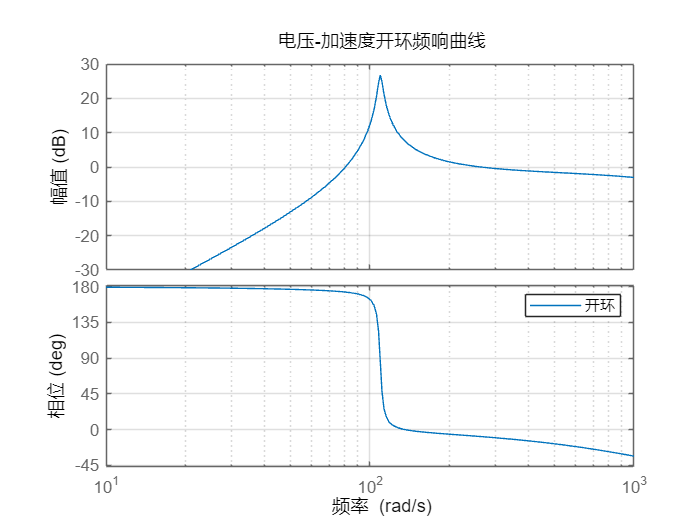

system = ss(A,B,C,D);

%% 开环系统伯德图
figure
bode(system); % 绘制伯德图

title('电压-加速度开环频响曲线')
grid on % 显示网格
h1 = gcf; % 获取当前图形句柄
% 设置频率范围（以rad/s为单位）
set(h1.Children(3), 'XLim', [10, 1000]); % 频率范围
% 设置增益范围（以分贝为单位）
set(h1.Children(3), 'YLim', [-30, 30]); % 增益范围
legend('开环') % 显示图例

%%%%% 

## LQR控制

%% LQR增益求解

Q1 = [1      0   0;
      0    1000  0;
      0      0   1];
Q2 = [1      0   0;
      0  10000   0;
      0      0   1];
Q3 = [1      0   0;
      0 100000   0;
      0      0   1];
R = 1;
K1 = lqr(system,Q1,R)

K1 =  -192.1826   26.9266    0.2542


K2 = lqr(system,Q2,R)

K2 =  -667.3071   94.8918    0.3241


K3 = lqr(system,Q3,R)

K3 = 1.0e+03 *

   -2.0922    0.3106    0.0005


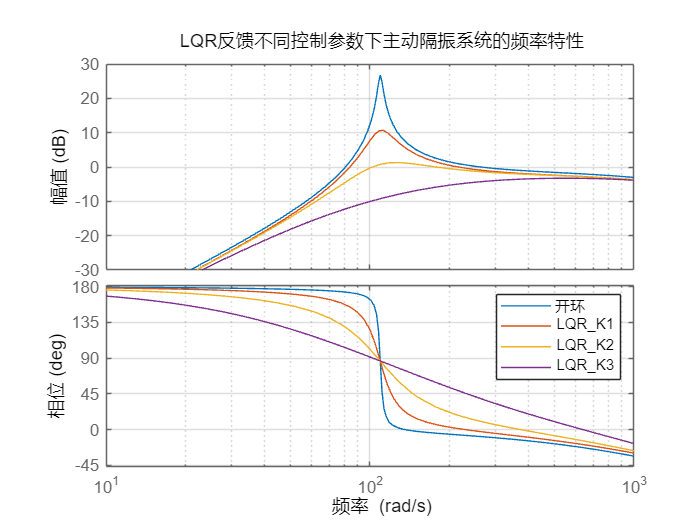


%% 新系统建立
system_LQR1 = ss(A-B*K1,B,C,D);
system_LQR2 = ss(A-B*K2,B,C,D);
system_LQR3 = ss(A-B*K3,B,C,D);

%% LQR控制系统伯德图
figure
bode(system);
hold on
bode(system_LQR1); % 绘制伯德图
hold on
bode(system_LQR2); % 绘制伯德图
hold on
bode(system_LQR3); % 绘制伯德图

title('LQR反馈不同控制参数下主动隔振系统的频率特性')
h2 = gcf; % 获取当前图形句柄
% 设置频率范围（以rad/s为单位）
set(h2.Children(3), 'XLim', [10, 1000]); % 频率范围
% 设置增益范围（以分贝为单位）
set(h2.Children(3), 'YLim', [-30, 30]); % 增益范围
grid on % 显示网格
legend('开环','LQR_K1','LQR_K2','LQR_K3') % 显示图例